# Optimization of PID parameters for robot control position

#### Adapted Original Version

t_max = 5;

### Open-loop response: Motor 1

% Initial data
time = 0:0.05:t_max;

% Create plant
K=13.86;
T=0.0002648;
plant = tf(K,[T 1 0]);

%figure("Name","Open-loop Step Response for system");
%step(plant,0:0.05:t_max);

### Closed-loop response: Motor 1

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.7;
config.CR = 0.5;
config.maxPIDValue = 1;% At initialization

% PID otimization
%Solutionv1_1 = Control_PID_modified(plant,config,"motor 1")
Solutionv1_1 = Control_PID(plant,config,"motor 1")

% PID parameters 
% Kp1 = Solutionv1_1.bestmem(1);
% Ki1 = Solutionv1_1.bestmem(2);
% Kd1 = Solutionv1_1.bestmem(3);

% Create the PID controller 
% Form: Kd*s + Kp + Ki/s
% C1 = tf([Kd1 Kp1 Ki1], [1 0]);
% C1 = pid(Kp1,Ki1,Kd1);

% Create the closed-loop system
% control_response1 = feedback(C1*plant, 1);

% Plot the step response
% figure("Name","PID Optimization for position control: motor 1 ");
% y = step(control_response1, time);
% plot(time, y, '-r', 'DisplayName', 'Estimated tf')
% grid on
% xlabel('Time (s)', 'FontSize', 12)
% ylabel('Position', 'FontSize', 12)
% title('Optimized Closed-loop Step Response: motor 1')
% legend('Location', 'best')

% version - original old
% Kp1 = 18.511011;
% Ki1 = 0;
% Kd1 = 0.493401;

% version - original
% bestmem: [11.8483 0.1859 0.0039] 
% error: 0.2149 
% Kp1 = 11.8483;
% Ki1 = 0.1859;
% Kd1 = 0.0039;

% Version - fixed 
% bestmem: [3.3180 0.1642 0.1163]
% error: 0.3370


### Open-loop response: Motor 2

% Create plant
K=32.8;
T=0.2307;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

### Closed-loop response: Motor 2

Iteration: 5
Best Error: 0.2946 | Worst Error: 0.3858 | Global Error: 6.7746
PID Parameters - Kp: 9.9682 | Ki: 1.6730 | Kd: 3.3581

Iteration: 10
Best Error: 0.2261 | Worst Error: 0.2929 | Global Error: 5.1926
PID Parameters - Kp: 10.1484 | Ki: 10.5105 | Kd: 0.4994

Iteration: 15
Best Error: 0.1897 | Worst Error: 0.2242 | Global Error: 4.1028
PID Parameters - Kp: 15.8923 | Ki: 19.9820 | Kd: 0.2057

Iteration: 20
Best Error: 0.1802 | Worst Error: 0.1972 | Global Error: 3.7800
PID Parameters - Kp: 17.9852 | Ki: 20.5596 | Kd: 0.0000



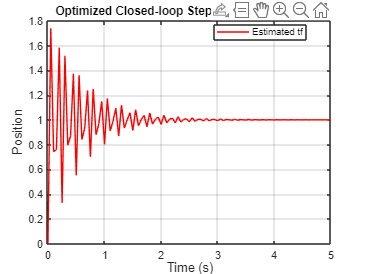

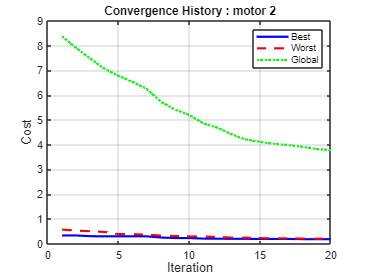

Solutionv1_2 = struct with fields:
       bestmem: [17.9852 20.5596 0]
         error: 0.1802
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

% Differential Evolution initial parameters
% config = struct();
% config.populationSize = 20;
% config.maxIterations = 30;
% config.F = 1;
% config.CR = 0.5;
% config.maxPIDValue = 2;% At initialization
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.5;
config.CR = 0.5;
config.maxPIDValue = 6;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 0;
joint4_ctrl = 0;
joint5_ctrl = 0;
joint6_ctrl = 0;

% PID otimization
Solutionv1_2 = Control_PID2(plant,config,": motor 2")

 
% bestmem: [6.8477 0 0.7081]
% error: 0.3904

% bestmem: [0.8422 0.5569 0.8399]
% error: 0.3911

% bestmem: [0.7898 0.1023 0.7679]
% error: 0.5418



% Solutionv1_2 = 
% bestmem: [0.5082 0.8534 0.6838]
% error: 0.4811


% config.populationSize = 20;
% config.maxIterations = 20;
% config.F = 0.7;
% config.CR = 1;
% config.maxPIDValue = 5;% At initialization
% Solutionv1_2 = 
% bestmem: [17.7028 18.4274 0.0104]
% error: 0.1964
% Funciona

% Nuevo funciona!!!
% Solutionv1_2 = struct with fields:
% bestmem: [17.9852 20.5596 0]
% error: 0.1802


% config.maxPIDValue = 3;% At initialization
% prueba 1
% Solutionv1_2 = 
% bestmem: [12.3782 0 1.2419]
% error: 0.2714

% config.maxPIDValue = 2.5;% At initialization
% Solutionv1_2 = 
% bestmem: [11.8651 0.0902 1.5077]
% error: 0.2760


% config.maxPIDValue = 2;% At initialization y modelo_opt
% Kp 6.8546
% Ki 0.002
% Kd 2.3968
% error = 0.3318

% config.maxPIDValue = 2;% At initialization y modelo_orig
% 8min
% bestmem: [12.5526 0 1.0084]
% error: 0.2689

% config.maxPIDValue = 2;% At initialization y modelo_orig2
% 10min 
% Solutionv1_2 = 
% bestmem: [9.1258 0.0598 2.2645]
% error: 0.3014
% Funciona se parece al de kP 6


% config.populationSize = 20;
% config.maxIterations = 30;
% config.F = 1;
% config.CR = 0.5;
% config.maxPIDValue = 2;% At initialization
% Solutionv1_2 = 
% bestmem: [70.7197 28.9111 3.6063]
% error: 0.1059



% PID parameters 
% Kp2 = Solutionv1_2.bestmem(1);
% Ki2 = Solutionv1_2.bestmem(2);
% Kd2 = Solutionv1_2.bestmem(3);
% 
% % Create the PID controller 
% % Form: Kd*s + Kp + Ki/s
% % C1 = tf([Kd1 Kp1 Ki1], [1 0]);
% C2 = pid(Kp2,Ki2,Kd2);
% 
% % Create the closed-loop system
% control_response2 = feedback(C2*plant, 1);

% % Plot the step response
% figure("Name","PID Optimization for position control: motor 2 ");
% y = step(control_response2, time);
% plot(time, y, '-r', 'DisplayName', 'Estimated tf')
% grid on
% xlabel('Time (s)', 'FontSize', 12)
% ylabel('Position', 'FontSize', 12)
% title('Optimized Closed-loop Step Response: motor 2')
% legend('Location', 'best')

% figure('Name', 'Convergence History for PID optimization');
% plot(1:20, Solutionv1_1.CONV.MIN, 'b-', 'LineWidth', 2);
% hold on;
% plot(1:20, Solutionv1_1.CONV.MAX, 'r--', 'LineWidth', 2);
% plot(1:20, Solutionv1_1.CONV.GLOBAL, 'g:', 'LineWidth', 2);
% xlabel('Iteration', 'FontSize', 12);
% ylabel('Cost', 'FontSize', 12);
% title('Convergence History: motor 2');
% legend('Best', 'Worst', 'Global', 'Location', 'NorthEast');
% grid on;
% hold off;

% Kp3 = 3;
% Ki3 = 3;
% Kd3 = 3;
% 
% Kp4 = 3;
% Ki4 = 3;
% Kd4 = 3;
% 
% Kp5 = 3;
% Ki5 = 3;
% Kd5 = 3;
% 
% Kp6 = 3;
% Ki6 = 3;
% Kd6 = 3;


### Open-loop response: Motor 3

% Create plant
K=29.85;
T=0.001451;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

### Closed-loop response: Motor 3

Iteration: 5
Best Error: 0.3384 | Worst Error: 0.4221 | Global Error: 7.3942
PID Parameters - Kp: 9.6609 | Ki: 10.8598 | Kd: 0.6054

Iteration: 10
Best Error: 0.3357 | Worst Error: 0.3588 | Global Error: 6.8237
PID Parameters - Kp: 9.8366 | Ki: 9.9739 | Kd: 0.8896

Iteration: 15
Best Error: 0.3279 | Worst Error: 0.3382 | Global Error: 6.7004
PID Parameters - Kp: 9.3406 | Ki: 14.0338 | Kd: 0.6717

Iteration: 20
Best Error: 0.3151 | Worst Error: 0.3323 | Global Error: 6.4796
PID Parameters - Kp: 9.2812 | Ki: 16.0853 | Kd: 0.7250

Iteration: 25
Best Error: 0.3116 | Worst Error: 0.3195 | Global Error: 6.2989
PID Parameters - Kp: 9.3956 | Ki: 17.2427 | Kd: 0.5501

Iteration: 30
Best Error: 0.3076 | Worst Error: 0.3112 | Global Error: 6.1981
PID Parameters - Kp: 9.1803 | Ki: 18.8143 | Kd: 0.3100



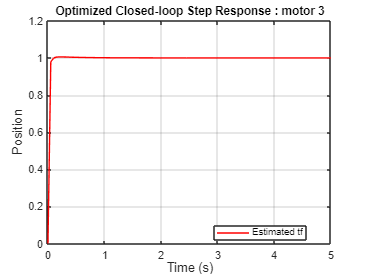

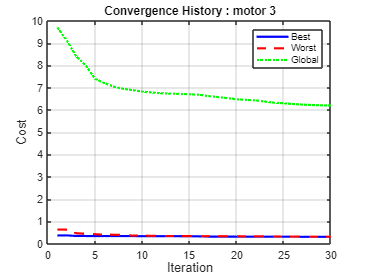

Solutionv1_2 = struct with fields:
       bestmem: [9.1803 18.8143 0.3100]
         error: 0.3076
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

% Differential Evolution initial parameters
% config = struct();
% config.populationSize = 20;
% config.maxIterations = 40;
% config.F = 0.5;
% config.CR = 0.5;
% config.maxPIDValue = 6;% At initialization

config = struct();
config.populationSize = 20;
config.maxIterations = 30;
config.F = 0.6;
config.CR = 0.5;
config.maxPIDValue = 7;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 70;
joint4_ctrl = 0;
joint5_ctrl = 0;
joint6_ctrl = 0;

% PID otimization
Solutionv1_2 = Control_PID2(plant,config,": motor 3")


% config = struct();
% config.populationSize = 20;
% config.maxIterations = 20;
% config.F = 0.7;
% config.CR = 0.5;
% config.maxPIDValue = 5;% At initialization
% Solutionv1_2 = 
% bestmem: [15.6143 72.1112 0.0851]
% error: 0.2350

% Iteration: 5
% Best Error: 0.3445 | Worst Error: 0.4558 | Global Error: 8.2098
% PID Parameters - Kp: 6.8227 | Ki: 9.2459 | Kd: 0.3407
% 
% Iteration: 10
% Best Error: 0.3219 | Worst Error: 0.3886 | Global Error: 6.9475
% PID Parameters - Kp: 7.5710 | Ki: 14.1220 | Kd: 0.0000
% 
% Iteration: 15
% Best Error: 0.2715 | Worst Error: 0.3271 | Global Error: 6.0359
% PID Parameters - Kp: 11.6785 | Ki: 37.8982 | Kd: 0.1216
% 
% Iteration: 20
% Best Error: 0.2350 | Worst Error: 0.2985 | Global Error: 5.2691
% PID Parameters - Kp: 15.6143 | Ki: 72.1112 | Kd: 0.0851

%-----
% Solutionv1_2 = 
%        bestmem: [10.3105 25.0217 0.8880]
%          error: 0.2991


% config.maxIterations = 30;
% Solutionv1_2 = struct with fields:
%bestmem: [17.6288 95.5768 0.1325]
%error: 0.2255

% config.maxIterations = 30;
% config.F = 1;
% Solutionv1_2 = struct with fields:
% bestmem: [59.0392 17.2550 5.7582]
% error: 0.1524

% config.F = 0.5;
% config.maxPIDValue = 6;% At initialization
% Solutionv1_2 = struct with fields:
% bestmem: [10.0579 19.2765 0]
% error: 0.2988
% Muy cercano a lo esperado

% config.maxPIDValue = 7;% At initialization
% Solutionv1_2 = struct with fields:
% bestmem: [26.8601 9.5535 0.0553]
% error: 0.3023


% config = struct();
% config.populationSize = 20;
% config.maxIterations = 40;
% config.F = 0.5;
% config.CR = 0.5;
% config.maxPIDValue = 7;% At initialization
% Solutionv1_2 = struct with fields:
% bestmem: [11.5494 42.3954 0]
% error: 0.2645


% config = struct();
% config.populationSize = 20;
% config.maxIterations = 40;
% config.F = 0.5;
% config.CR = 0.5;
% config.maxPIDValue = 6;% At initialization
% 
% Solutionv1_2 = struct with fields:
% bestmem: [9.2892 16.8208 0.0153]
% error: 0.3054
% Funcional!!!

%Nueva version
% config = struct();
% config.populationSize = 20;
% config.maxIterations = 20;
% config.F = 0.5;
% config.CR = 0.5;
% config.maxPIDValue = 6;% At initialization
% Solutionv1_2 = struct with fields:
% bestmem: [8.0832 16.2568 0.0156]
% error: 0.3092

%Nueva version - 
% config = struct();
% config.populationSize = 20;
% config.maxIterations = 30;
% config.F = 0.4;
% config.CR = 0.5;
% config.maxPIDValue = 6;% At initialization
% Solutionv1_2 = struct with fields:
% bestmem: [7.7569 7.7749 0.0639]
% error: 0.3384


% config = struct();
% config.populationSize = 20;
% config.maxIterations = 30;
% config.F = 0.6;
% config.CR = 0.5;
% config.maxPIDValue = 7;% At initialization
% Solutionv1_2 = struct with fields:
% bestmem: [9.1803 18.8143 0.3100]
% error: 0.3076
% cercano

### Open-loop response: Motor 4

% Create plant
% Identificando: q4 [0 : -50]
K=-10.06;
T=0.3432;
plant = tf(K,[T 1 0]);

% Identificando: q4 [0 : 50]
% K=14.5;
% T=0.04741;
% plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

### Closed-loop response: Motor 4

Iteration: 5
Best Error: 0.1888 | Worst Error: 0.2986 | Global Error: 4.9986
PID Parameters - Kp: 9.3185 | Ki: 5.0614 | Kd: 0.5549

Iteration: 10
Best Error: 0.1544 | Worst Error: 0.2141 | Global Error: 3.5961
PID Parameters - Kp: 13.9861 | Ki: 2.7681 | Kd: 0.0000

Iteration: 15
Best Error: 0.1449 | Worst Error: 0.1543 | Global Error: 2.9932
PID Parameters - Kp: 18.7335 | Ki: 5.9502 | Kd: 0.0426

Iteration: 20
Best Error: 0.1445 | Worst Error: 0.1468 | Global Error: 2.9093
PID Parameters - Kp: 28.6230 | Ki: 11.6376 | Kd: 0.0637



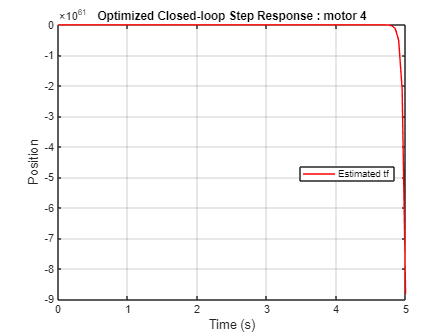

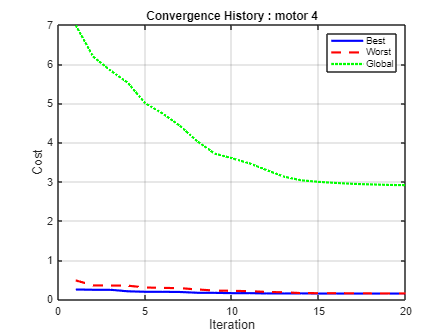

Solutionv1_2 = struct with fields:
       bestmem: [28.6230 11.6376 0.0637]
         error: 0.1445
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.5;
config.CR = 0.5;
config.maxPIDValue = 6;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 70;
joint4_ctrl = 50;
joint5_ctrl = 0;
joint6_ctrl = 0;

% PID otimization
Solutionv1_2 = Control_PID2(plant,config,": motor 4")


% Solutionv1_2 = struct with fields:
% bestmem: [28.6230 11.6376 0.0637]
% error: 0.1445


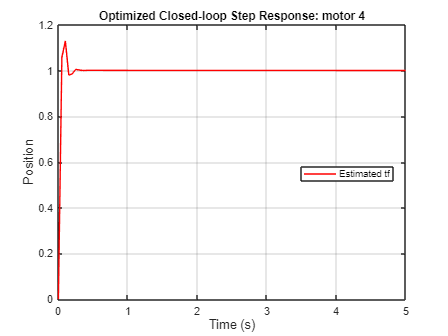

K=14.5;
T=0.04741;
plant = tf(K,[T 1 0]);

Kp2 = 28.6230;
Ki2 = 11.6376;
Kd2 = 0.0637;

% Create the PID controller 
% Form: Kd*s + Kp + Ki/s
% C1 = tf([Kd1 Kp1 Ki1], [1 0]);
C2 = pid(Kp2,Ki2,Kd2);

% Create the closed-loop system
control_response2 = feedback(C2*plant, 1);

% Plot the step response
figure("Name","PID Optimization for position control: motor 4 ");
y = step(control_response2, time);
plot(time, y, '-r', 'DisplayName', 'Estimated tf')
grid on
xlabel('Time (s)', 'FontSize', 12)
ylabel('Position', 'FontSize', 12)
title('Optimized Closed-loop Step Response: motor 4')
legend('Location', 'best')

### Open-loop response: Motor 5

% Create plant
% Identificando: q5 [0 : 60]
K=14.02;
T=0.0003768;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

### Closed-loop response: Motor 5

Iteration: 5
Best Error: 0.1904 | Worst Error: 0.2908 | Global Error: 4.9838
PID Parameters - Kp: 9.4372 | Ki: 1.0222 | Kd: 0.0000

Iteration: 10
Best Error: 0.1834 | Worst Error: 0.1976 | Global Error: 3.7634
PID Parameters - Kp: 10.2720 | Ki: 0.0000 | Kd: 0.0000

Iteration: 15
Best Error: 0.1792 | Worst Error: 0.1838 | Global Error: 3.6258
PID Parameters - Kp: 11.4137 | Ki: 0.0851 | Kd: 0.0000

Iteration: 20
Best Error: 0.1758 | Worst Error: 0.1791 | Global Error: 3.5558
PID Parameters - Kp: 12.3126 | Ki: 0.1702 | Kd: 0.0000



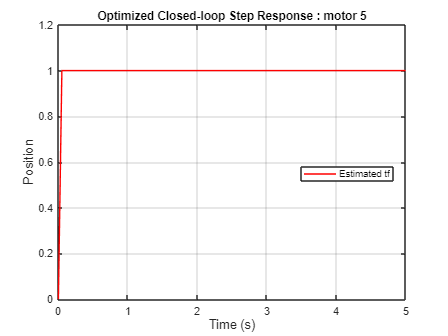

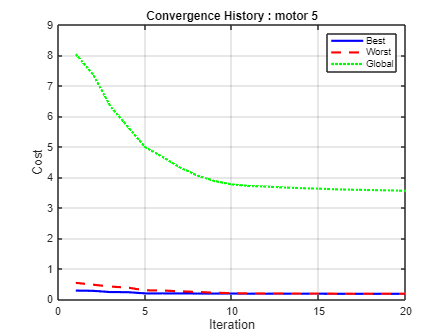

Solutionv1_2 = struct with fields:
       bestmem: [12.3126 0.1702 0]
         error: 0.1758
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.5;
config.CR = 0.5;
config.maxPIDValue = 6;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 70;
joint4_ctrl = 50;
joint5_ctrl = 60;
joint6_ctrl = 0;

% PID otimization
Solutionv1_2 = Control_PID2(plant,config,": motor 5")

% Solutionv1_2 = struct with fields:
%bestmem: [12.3126 0.1702 0]
%error: 0.1758

### Open-loop response: Motor 6

% Create plant
% Identificando: q5 [0 : 60]
K=9.31;
T=0.001593;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop Step Response for system");
% step(plant,0:0.05:t_max);

### Closed-loop response: Motor 6

Iteration: 5
Best Error: 0.1686 | Worst Error: 0.2299 | Global Error: 3.9006
PID Parameters - Kp: 8.0811 | Ki: 1.3381 | Kd: 1.2314

Iteration: 10
Best Error: 0.1182 | Worst Error: 0.1673 | Global Error: 2.7050
PID Parameters - Kp: 10.6305 | Ki: 0.9076 | Kd: 0.0000

Iteration: 15
Best Error: 0.1009 | Worst Error: 0.1175 | Global Error: 2.1837
PID Parameters - Kp: 12.5610 | Ki: 0.0000 | Kd: 0.0000

Iteration: 20
Best Error: 0.0969 | Worst Error: 0.1030 | Global Error: 2.0065
PID Parameters - Kp: 14.2833 | Ki: 0.0000 | Kd: 0.0000



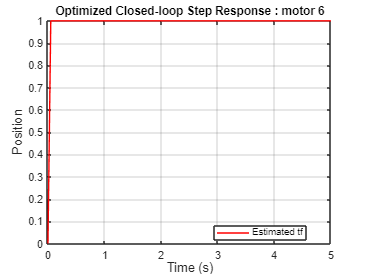

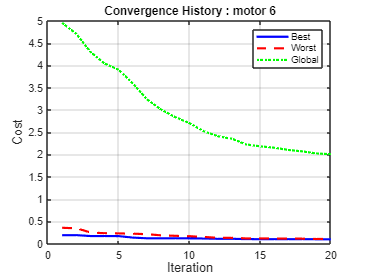

Solutionv1_2 = struct with fields:
       bestmem: [14.2833 0 0]
         error: 0.0969
    population: [20×4 double]
          CONV: [1×1 struct]
             M: [1×1 tf]

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.5;
config.CR = 0.5;
config.maxPIDValue = 6;% At initialization

joint1_ctrl = 60;
joint2_ctrl = 140;
joint3_ctrl = 70;
joint4_ctrl = 50;
joint5_ctrl = 60;
joint6_ctrl = 40;

% PID otimization
Solutionv1_2 = Control_PID2(plant,config,": motor 6")


%Solutionv1_2 = struct with fields:
% bestmem: [14.2833 0 0]
% error: 0.0969